# Working with Dates and Times

Previously, we introduced four types of non-numeric data: **datetime, duration, text, and categorical. **This reading covers the first two of these four data ty`pes. Here, with datetime and duration variables, you'll perform some of the tasks you've already seen, and you'll work through some new tasks.

To get started, import the table of pizza orders by running the live script you generated using the Import Tool.

load orders.mat

## Datetime

Datetime variables are a type of non-numeric data that represent points in time. 

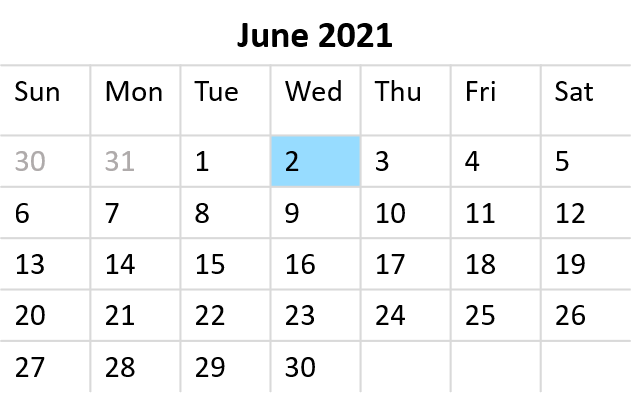

The pizza orders dataset contains three `datetime` variables:

- `ReceivedTime` - time when the order was received

- `StartedTime`  - time when the pizza started being prepared

- `ReadyTime` - time when the pizza was finished and ready for the customer

Notice that the values contain both a date and a specific time of day:

orders.ReceivedTime

ans = 3085×1 datetime array
   07-Jun-2021 11:10:26
   07-Jun-2021 11:12:48
   07-Jun-2021 11:12:48
   07-Jun-2021 11:18:39
   07-Jun-2021 11:33:39
   07-Jun-2021 12:11:28
   07-Jun-2021 12:11:28
   07-Jun-2021 12:50:02
   07-Jun-2021 12:50:02
   07-Jun-2021 12:50:02
   07-Jun-2021 12:50:02
   07-Jun-2021 12:50:02
   07-Jun-2021 12:50:02
   07-Jun-2021 12:50:02
   07-Jun-2021 13:35:30
   07-Jun-2021 13:35:30
   07-Jun-2021 13:35:30
   07-Jun-2021 13:35:30
   07-Jun-2021 13:49:59
   07-Jun-2021 14:03:23
   07-Jun-2021 14:12:33
   07-Jun-2021 14:12:33
   07-Jun-2021 14:12:33
   07-Jun-2021 14:56:01
   07-Jun-2021 14:56:01
   07-Jun-2021 15:37:09
   07-Jun-2021 15:37:09
   07-Jun-2021 15:37:09
   07-Jun-2021 15:37:09
   07-Jun-2021 16:14:57


### Visualizing Datetime Variables

How can you use this data to see the trend in pizza orders? Plot the numeric variable `OrderNumber` against the datetime variable `ReceivedTime` to use the datetime values in a visualization.

plot(orders.ReceivedTime,orders.OrderNumber)
xlabel("Time received")
ylabel("Order number")
title("Pizza Orders Over Time")

The x-axis of this graph has ticks for the start of each day. The plot shows the trend in orders each day and how the trend changed throughout the week. The orders increased slowly from June 07 to June 10 (Monday-Thursday) but rapidly on June 11 and June 12 (Friday and Saturday).

Use the interactive **Zoom In **tool to see the data from a single day in greater detail. 

Notice how the x-axis labels dynamically update as you change the viewing window.

### Creating Datetime Variables

Sometimes, dates and times are not stored in tabular data as a single entity like `"07-Jun-2021 11:12"` but instead with separate columns for the year, month, day, and time of day. How can you assemble these values into a datetime variable?

Let's say you have data stored in three separate vectors:

myDay = [1;2;3;4;5]
myMonth = [6;6;6;6;6]
myYear = [2021;2021;2021;2021;2021]

Combine these values into a datetime variable with the function `datetime`:

myDate = datetime(myYear,myMonth,myDay)

You can also provide additional vectors for the hour, minutes, and seconds. See the [`datetime`](https://www.mathworks.com/help/matlab/ref/datetime.html) documentation for examples.

### Formatting Datetime Variables

The variable `myDate` shows only a date, but all datetime variables also contain the exact time of day, even down to the nanosecond. You can change the format of a datetime variable to show more or less information. This doesn't change the underlying values, only the appearance. For example, you can use a very formal format:

myDate.Format = "eeee, MMMM d, yyyy h:mm a"

See [this documentation page](https://www.mathworks.com/help/matlab/matlab_prog/set-display-format-of-date-and-time-arrays.html) with explanations for the formatting syntax. A longer format can make displaying the values more cumbersome, but it avoids ambiguity such as the month/day order in "06/01/21"

### Extracting Numbers from Datetime Variables

Once you have a datetime variable, how can you extract the numeric value of the date or time of day? Use the functions named for specific units of time like `second`, `minute`, `hour`, `day`, `month`, and `year`. These functions will return the numeric values in a vector.

day(myDate)
hour(myDate)

Notice the hour values from `myDate` are 0, even though the string format shows "12:00 AM". The values returned by `hour` range from 0 to 24, so 12:00 AM has an hour value of 0.

### Practice with Datetime

Now it's your turn! Can you create a datetime variable that has your birthday? What day of the week were you born? Hint: check out the documentation for [day](https://www.mathworks.com/help/matlab/ref/datetime.day.html). How about the birthday of your favorite historical figure?

## Duration

Datetime variables are great for representing specific points in time, but `duration` variables are useful for representing how much time has passed between two points.

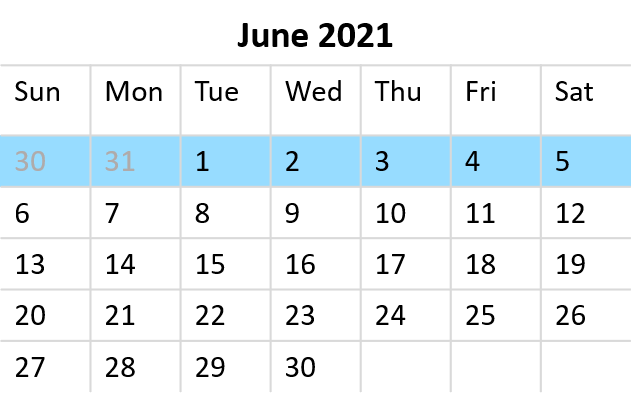

For example, calculate the total time it took to make each pizza by subtracting `ReceivedTime` from `ReadyTime`. Store this value in a new duration variable, `TotalDuration`.

orders.TotalDuration = orders.ReadyTime - orders.ReceivedTime

The `TotalDuration` values display the duration with the number of hours, minutes, and seconds:

orders.TotalDuration

### Formatting Duration Variables

None of the values in `TotalDuration` are above 1 hour, so it's more practical to change the display format to only display minutes. Similar to datetime variables, change the format of a duration variable by setting the `Format` to a string value that denotes the intended units:

-     `"s"` - seconds

-     `"m"` - minutes

-     `"h"` - hours

-     `"d"` - days

-     `"y"` - years 

orders.TotalDuration.Format = "m"

Now the values are in units of minutes. To see the distribution of duration values, create a histogram with this variable. Notice the units are displayed on the x-axis.

histogram(orders.TotalDuration)
xlabel("TotalDuration")
ylabel("Count")

### Creating Duration Variables

Duration variables are automatically created when you calculate the difference between two datetime variables. You can also import variables as duration variables when using the import tool.

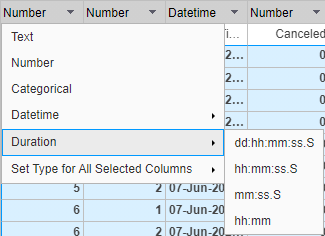

Additionally, you can create duration variables from numeric data. It is useful to do this, for example, when you have numeric, signal data from a sensor that records time in seconds. How do you create a duration variable from numeric data?

There are several functions for creating duration variables from numeric variables. They are named for the unit of time, for example, `seconds`, `minutes`, `hours`, `days`, and `years`. 

Create a duration variable by using a numeric variable as an input to the `seconds` function.

myDuration = seconds(0:600:3600)

These functions can also be used to convert duration variables to numeric variables. You can use any function (`hours` or `days`, for example), regardless of the function used to create the duration variable. 

hours(myDuration)

The output is a numeric variable with the number of hours, even though the variable was originally created with `seconds`.

### Modifying Datetime Data with Duration Variables

Another reason to use duration variables is to manipulate datetime data. For example, if a recorded datetime variable is off by some specific amount, how can you correct it?

Let's say you need to shift datetime values by one week. Use the `days` function to add or subtract seven days from the datetime variable.

myShiftedDate = myDate + days(7)

All the values are now shifted forward by one week.

### Practice with Duration

Use the birthday variable you created earlier to calculate the exact number of days from your birthday until today. Hint: the command `datetime("today")` will return a datetime value with today's date.

In this reading, you worked with datetime and duration variables and created meaningful visualizations with adaptive axis labels. Next, you will perform similar tasks with the remaining non-numeric data types for text and categorical data.

*Copyright 2021 The MathWorks, Inc.*